# Plotting Trajectories

We're now ready to start plotting trajectories!

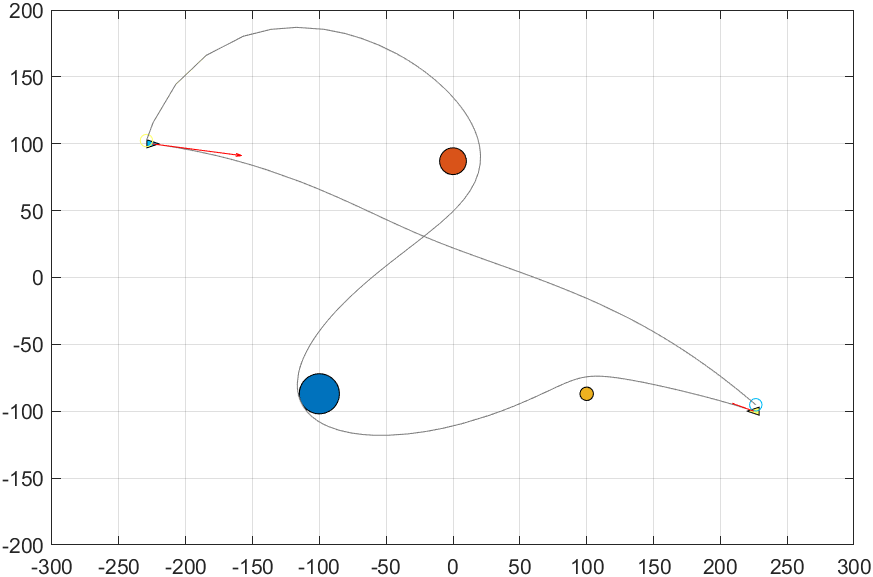

Here are the steps we'll follow:

- Use the `fixedMission` function to generate a mission map

- Use the sliders below to set the desired launch angle and velocity

- Use the `quiver` function to display this initial velocity vector

- Use the `launchPayload` function to compute the payload trajectory

- Use the `comet` function to animate this volley

## Generate Mission Map (Step 1)

To help speed-up our animations, we'll create a figure window outside of our live script by setting `"Visible"` to `"on".`

figure("Visible","on")
app = fixedMission

Recall, later when we create an app, our plotting commands (such as `quiver` and `comet`) will need to specify the target axes where we want our plot to be displayed.  When we begin creating our game in MATLAB App Designer, you'll see that the default name for the target axes will be "`UIAxes`", and it will be stored in an object named "`app`" (without quotes).  This is similar to how we used dot notation to store all of our mission map parameters in a single variable named `app`.

In general, we can extract a property from an object and store it in an output as follows:

% TASK 1: Use dot notation to extract the "UIAxes" property from the 
% "app" object and store it in an output named "ax" (without quotes).
% To do so, uncomment the line below and change output to ax, 
% object to app, and property to UIAxes (note the upper case letters).

% output = object.property

We'll also learn how to change the axes and grid color in App Designer; but if you'd like to do that now, you can do so by uncommenting the commands below.

% set(ax,"Color",[0 0 0])
% set(ax,"GridColor",[1 1 1])

## Set and Display the Launch Velocity Vector (Steps 2 & 3)

The `"ship"` variable indicates from which ship the payload will be launched.  You can then use the sliders to set the launch angle (`ang`) to a value between -90 (down) and 90 (up) degrees, and the velocity throttle (`vel`) to a value between 0% and 100%.

Hint:  For Ship 2, try setting both values to about 19 (after completing all the Tasks).

ship = 1;       % ship number (1 or 2)
ang =-7.5; % angle, [-90 90] degree
vel = 75; % velocity, [0 100] percent

As we did when plotting the body circles (with `ang` and `Rb`), we can use these `ang` and `vel` values with the cosine function (`cosd`) to generate the x-velocity value (`vx`) and the sine function (`sind`) to generate the y-velocity value (`vy`).  The cosine and sine functions output a number between -1 and 1, so we'll need to scale them by the velocity throttle.

% TASK 2: Scale vx and vy by multiplying cosd and sind by vel.
vx = cosd(ang);
vy = sind(ang);

And as we did when plotting the Ship 2 triangle, if we're launching a payload from Ship 2, we'll need to flip the x-velocity direction so it also points left (towards Ship 1).  Once again, to flip the sign of a number we just need to multiply it by a negative.

if (ship == 2)
    vx = -vx;  % This is the same as multiplying vx by -1
end

The inputs to the [`quiver`](https://www.mathworks.com/help/matlab/ref/quiver.html) function are then the target axes, the initial x and y launch position (from Ship 1 or Ship 2), the initial x and y launch velocity (`vx` and `vy`), and the arrow color (optional).

ax = app.UIAxes;    % in case Task 1 was not completed
delete(app.hq)      % delete previous quiver arrow
px = app.xs(ship);  % extract ship x-position
py = app.ys(ship);  % extract ship y-position

% TASK 3: Call the quiver function with the appropriate inputs
% by replacing the zeros below with the variables we created 
% for the x and y position and velocity (px, py, vx, vy).
app.hq = quiver(ax,0,0,0,0,"Color","red");

## Compute and Display the Payload Trajectory (Steps 4 & 5)

The `launchPayload` function requires the values for the launch angle (`ang`) and velocity throttle (`vel`) be stored in the `"app"` variable, along with our other parameters for the ship and body locations.  As such, we can add these parameters using dot notation, in the same way we added the ship and body parameters in the `fixedMission` function.  We'll also need to specify from which ship we are launching the payload, by once again using the `ship` variable; this time as the second input to `launchPayload` function. 

app.ang = ang;
app.vel = vel;
traj = launchPayload(app,ship);

The `launchPayload` function outputs the payload trajectory (`traj`) as a matrix containing the `x` and `y` position at each time step.  Each row corresponds to a particular time and the two columns correspond to the `x` and `y` positions, respectively.

Recall that we can use indexing to extract a column from a matrix using the colon (`:`) operator to select all the rows, along with the desired column number.  For example, below we are extracting the third column from a matrix named `data`.

% TASK 4: Use indexing to extract the first column from the matrix 
% traj and store the result in x (instead of 0 below). Likewise,
% extract the second column from traj and store the result in y.
x = 0;
y = 0;

The inputs to the [`comet`](https://www.mathworks.com/help/matlab/ref/comet.html) function are then the target axes and the `x` and `y` positions we just extracted from the computed trajectory matrix (`traj`).

% TASK 5: Call the comet function with the appropriate inputs
% by replacing the zeros below with the variables we created 
% for the x and y postion of the trajectory.
comet(ax,0,0)

## Solutions

#### Task 1

#### Task 2

#### Task 3

#### Task 4

#### Task 5

Copyright 2022 The MathWorks, Inc.